# Homework 3 problem 4.43

clear; close; clc;

## Declare Variables

domain = [-5,5];
range = [-5,5];
n_pointsPlot = 1000;

## solve for value of lagrange multiplier at optimum

syms v
solve(8*(4+v+20) + 5*(-v-20)+v-8==0,v)

$$ans = -21$$

## Plot solution

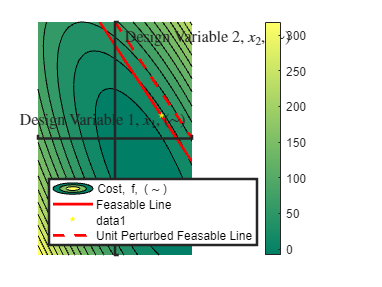


x_1 = linspace(domain(1), domain(2), floor(sqrt(n_pointsPlot)));
x_2 = linspace(range(1), range(2), floor(sqrt(n_pointsPlot)));

[x_1_grid, x_2_grid] = meshgrid(x_1,x_2);


f = 4*x_1_grid.^2 + 3*x_2_grid.^2 + 5*x_1_grid.*x_2_grid - 8*x_1_grid;

contourf(x_1_grid, x_2_grid, f, 15, "LineWidth",.001, "DisplayName","Cost, f, (\sim)"); colormap("summer"); colorbar;
zlabel("Cost, f, (\sim)",Interpreter="latex");
xlabel("Design Variable 1, $x_1$, $(\sim)$", "Interpreter","latex", "FontSize",12);
ylabel("Design Variable 2, $x_2$, $(\sim)$", "Interpreter","latex", "FontSize",12);
xlim(domain); ylim(range);

% plot the constraint
hold on
fimplicit(@(x,y) x + y - 4, [domain, range], "r","LineWidth",2, "DisplayName","Feasable Line");
legend("Location","southwest")

% plot the optimum
plot(3,1,"Marker","pentagram","MarkerSize",3,"MarkerEdgeColor",[1,1,0],"MarkerFaceColor",[1,1,0],"LineStyle","none")

% plot the perturb contrain
hold on
fimplicit(@(x,y) x + y - 5, [domain, range], "--r","LineWidth",2, "DisplayName","Unit Perturbed Feasable Line");
legend("Location","southwest")

%axes1 = axes('Parent',gcf);
box(gca,'off');
set(gca,'BoxStyle','full','Layer','top','XAxisLocation','origin',...
    'YAxisLocation','origin');
set(gca,"LineWidth",2)


% this is an equality contraint so only the feasible region is true
% boundrayEdges_Xcoords = [x_1, fliplr(x_1)];
% boundrayEdges_Ycoords = [4-x_1, range(1) * ones(1,length(x_2))];
% fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0], "DisplayName","infeasible region")